% 호랑이
clc, clear

addpath('functions')
imds = imageDatastore('images\many_images\tiger', 'LabelSource', 'foldernames', 'IncludeSubfolders',true);

tbl = countEachLabel(imds)

tbl = 1×2 table
    Label    Count
    _____    _____

    tiger    1247 


% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, 0.7, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 1×2 table
    Label    Count
    _____    _____

    tiger     873 


% Load pretrained network
net = resnet50();

% Number of class names for ImageNet classification task
numel(net.Layers(end).ClassNames)

ans = 1000

[trainingSet, testSet] = splitEachLabel(imds, 0.7, 'randomize');

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
imageSize = net.Layers(1).InputSize;
tic
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet);
augmentedTestSet = augmentedImageDatastore(imageSize, testSet);

names = net.Layers(end).ClassNames;

featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels;

% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.
classifier = fitcsvm(trainingFeatures',trainingLabels,'KernelScale','auto','Standardize',true,...
    'OutlierFraction',0.05);
toc

경과 시간은 70.163169초입니다.


% Extract test features using the CNN
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Pass CNN image features to trained classifier
[~,scores_tiger_train] = predict(classifier, trainingFeatures, 'ObservationsIn', 'columns');

[predictedLabels,scores_tiger] = predict(classifier, testFeatures, 'ObservationsIn', 'columns');

% Get the known labels
testLabels = testSet.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels);

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat = 1

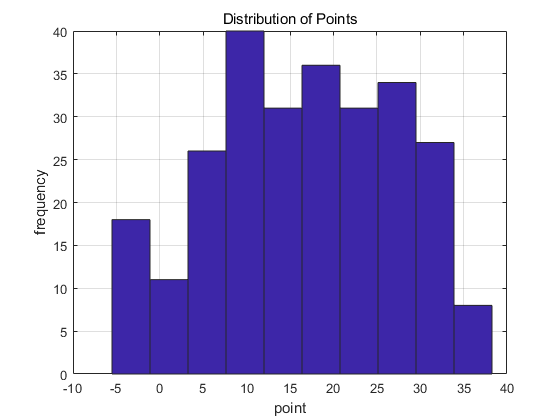

figure
hist(scores_tiger)
title('Distribution of Points')
xlabel('point')
ylabel('frequency')
grid()

% Display the mean accuracy
mean(diag(confMat))

ans = 1

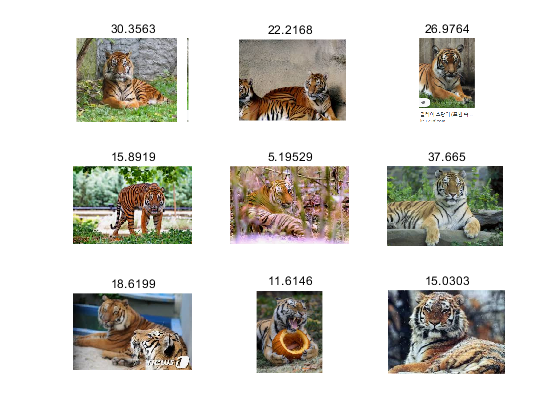

figure
for i=1:9
    testImage = readimage(testSet,i);
    testLabel = testSet.Labels(1);
    ds = augmentedImageDatastore(imageSize, testImage);
    imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
    [~, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
    subplot(3,3,i)
    imshow(testImage)
    title(score)
end

% caomparison between good and poor predictions
error_idx = [];
error_score = [];
good_idx = [];
good_score=[];
k=1;
g=1;
for i=1:length(testSet.Files)
    testImage = readimage(testSet,i);
    ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
    imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
    [~, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
    if score<0.5
        error_idx(k) = i;
        error_score(k) = score;
        k=k+1;
    elseif score>30
        good_score(g) = score;
        good_idx(g) = i;
        g=g+1;
    end
end

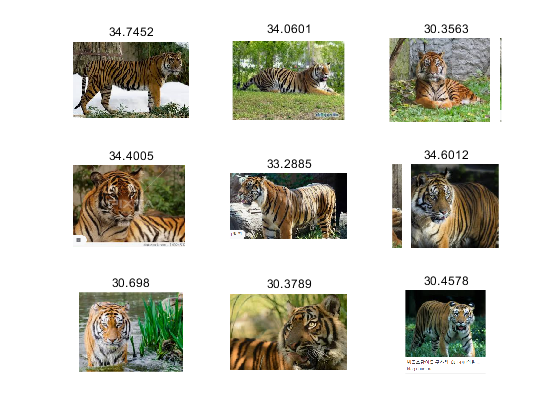

% Make a prediction using the classifier
figure
idx = randperm(length(good_idx),9);
for i = 1:9
    subplot(3,3,i)
    j = idx(i);
    k = good_idx(j);
    testImage = readimage(testSet,k);
    ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
    imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
    [~, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
    
    imshow(testImage)
    title(score)
end

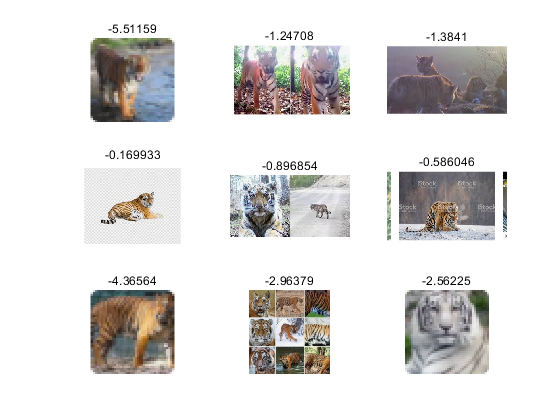

% inspect images estimated error predictions
figure
idx = randperm(length(error_idx),9);
figure
for i=1:9
    subplot(3,3,i)
    j = idx(i);
    k = error_idx(j);
    testImage = readimage(testSet,k);
    ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
    imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
    [~, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
    
    imshow(testImage)
    title(score)
    
    
end

testImage = imread('소나타_전방.png');
ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
[~, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
figure
imshow(testImage)
title(score)


testImage = imread('고양이.png');
ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
[~, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
figure
imshow(testImage)
title(score)

testImage = imread('사자.png');
ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
[~, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
figure
imshow(testImage)
title(score)


testImage = imread('샌들.png');
ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');
[predictedLabel, score] = predict(classifier, imageFeatures, 'ObservationsIn', 'columns');
figure
imshow(testImage)
title(score)
